读取文件：

[yeli, fs] = audioread("yeli.wav");
[luoruo, ~] = audioread("luoruo.wav");
[audio, ~]= audioread("audio.wav");
yeli = yeli(:,1);
luoruo = luoruo(:,1);
audio = audio(:,1);

罗云熙“夜里”发音：

soundsc(yeli, fs);

罗云熙“luoruo”发音：

soundsc(luoruo, fs);

音频：

soundsc(audio, fs);

specgram对比：

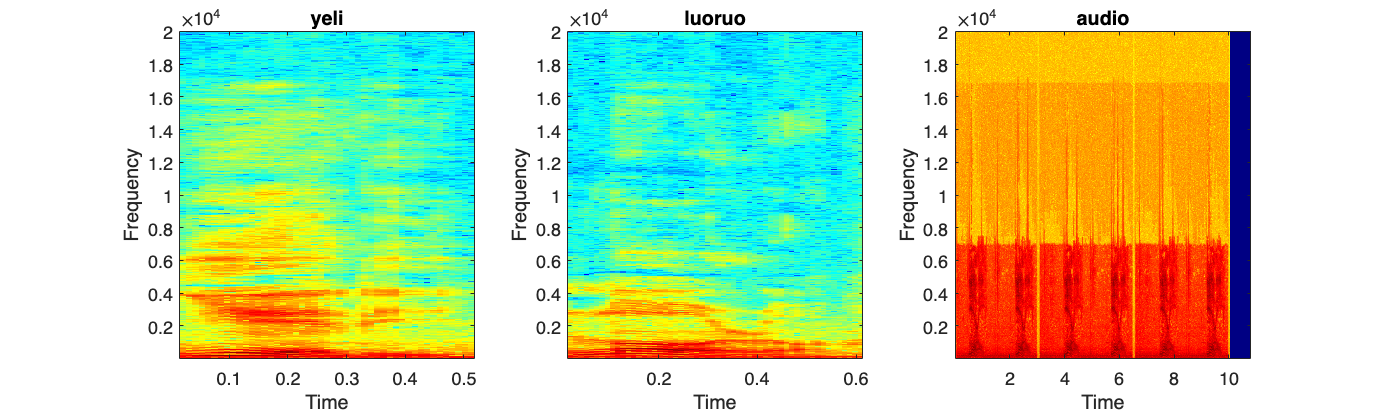

fig = figure(1);
fig.Position = [200 200 1000 300];
subplot(131)
specgram(yeli,2048,fs,2048,1536);
ylim([20, 20000]);title("yeli");
subplot(132)
specgram(luoruo,2048,fs,2048,1536);
ylim([20, 20000]);title("luoruo");
subplot(133)
specgram(audio,2048,fs,2048,1536);
ylim([20, 20000]);title("audio");

low pass filter - “luoruo”发音

soundsc(lowpass(audio,1,fs), fs)
audiowrite("lpf.wav", lowpass(audio,800,fs), fs)

high pass filter - “yeli”发音

soundsc(highpass(audio,1000,fs), fs)
audiowrite("hpf.wav", highpass(audio,1000,fs), fs)

变调 - "luoruo"发音

soundsc(audio, fs*1.5)
audiowrite("up.wav", audio, fs*1.5)

变调 - “yeli”发音

soundsc(audio, fs*0.5)
audiowrite("down.wav", audio, fs*0.5)